clear;
clc;
close all;

Setting up domain

Fs = 16000; % Samling frequency of my phone
dt = 1/Fs; % smallest time interval
StopTime = 2; % seconds
t = (0:dt:StopTime)'; % time vector
L = length(t); % number of samples

Generate signal

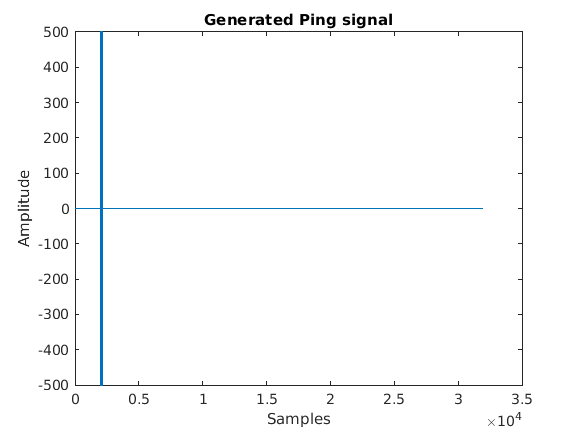

f0 = 2000; % in Hz
ping = zeros(L,1);
ping(2000:2160) = 500*sin(2*pi*f0*t(2000:2160)); % 160 samples is 10ms
plot(ping)
title('Generated Ping signal')
xlabel('Samples')
ylabel('Amplitude')

sound(ping) % This is recorded using smart phone for further processing

FFT for analysis

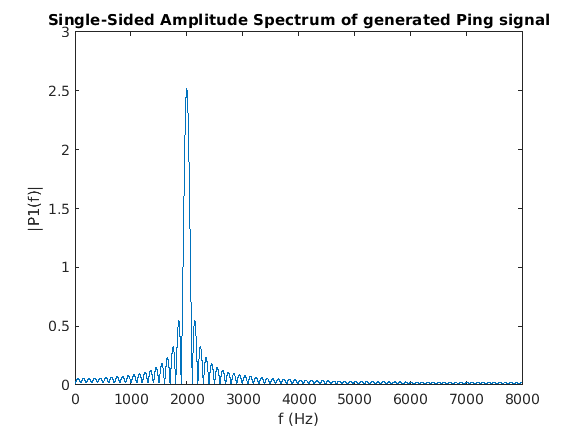

ping_fft = fft(ping);
P2 = abs(ping_fft/L);
P1 = P2(1:(L-1)/2 + 1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L; % frequency domain
plot(f,P1)
title('Single-Sided Amplitude Spectrum of generated Ping signal')
xlabel('f (Hz)')
ylabel('|P1(f)|')